close all; clc

% find equilibrium points
syms a positive
syms b nonzero
syms x1 x2

% find equilibrium points
f1 = (x1 - x2)*(1 - x1^2 - x2^2);
f2 = (x1 + x2)*(1 - x1^2 - x2^2);

sln = solve([f1==0, f2==0], [x1 x2]);
sln.x1

$$ans = \left(\begin{array}{c} 0\\ -1\\ 1 \end{array}\right)$$

sln.x2

$$ans = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

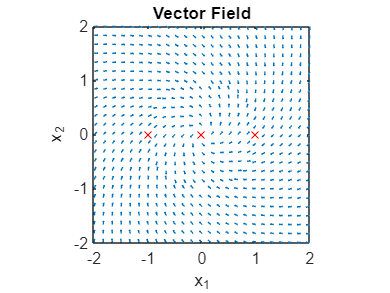

% Create vector field
x = linspace(-2,2,25);
y = linspace(-2,2,25);
[X,Y] = meshgrid(x,y);

DX = (X-Y).*(1 - X.^2 - Y.^2);
DY = (X+Y).*(1 - X.^2 - Y.^2);

N = sqrt(DX.^2 + DY.^2);
quiver(X,Y,DX./N,DY./N,0.3);
xlabel('x_1')
ylabel('x_2')
axis tight equal;
title("Vector Field")

% draws x's on the equilibrium points
hold on;
for i=1:numel(sln.x1)
    if isreal(sln.x1(i)) && isreal(sln.x2(i))
        plot(sln.x1(i), sln.x2(i), 'rx')
    end
end
hold off